1.請分別讀取2個.wav檔(一個為單聲道，一個為雙聲道)           

- 描述此音檔內容(flanger.wav   AND  welcome.wav)  **(20分)**

- flanger.wav 中文檔案

- welcome.wav 英文檔案                

- 畫出音檔的圖形(單聲畫一張圖，雙聲畫兩張圖)                         **(20分)**

- 播放聲音，描述該音檔內容     

            flanger.wav大家好我是費玉祥

            welcome.wav a burch new on the sweet camp?                                        

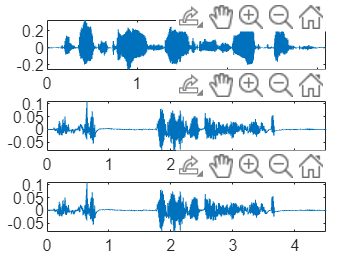

[y1, fs]=audioread('welcome.wav');
sound(y1, fs);	% 播放此音訊
time=(1:length(y1))/fs;	% 時間軸的向量
% 畫出時間軸上的波形



fileName='flanger.wav';
[y, fs]=audioread(fileName);	% 讀取音訊檔
%sound(y, fs);	% 播放音訊
left=y(:,1);	% 左聲道音訊
right=y(:,2);	% 右聲道音訊
subplot(3,1,1), plot(time, y1);
subplot(3,1,2), plot((1:length(left))/fs, left);
subplot(3,1,3), plot((1:length(right))/fs, right);

2.承上題

- 請變更音訊的震幅與取樣頻率(增加與降低)，描述音檔的變化    **(20分)**

            震幅決定聲音大小，震幅越大聲音越大反之亦然，取樣頻率決定清晰度

- 請將聲音訊號進行上下顛倒，描述音檔的變化 			**(20分)**

             聽到的聲音基本上是一樣的

[y1, fs]=audioread('welcome.wav');
sound(y1*2,fs),pause(3)
sound(y1*0.5,fs),pause(3)
y1=y1*(-2)

y1 =          0
   -0.0001
    0.0001
         0
   -0.0001
         0
         0
         0
         0
   -0.0001


sound(y1,fs),pause(3)





- 請使用matlab 錄製自己一段聲音，並存成wav檔(檔名：學號+名字)

- 畫出此音檔之頻譜圖(spectrogram)並與此音檔之波型圖比較(描述觀察到的變化)

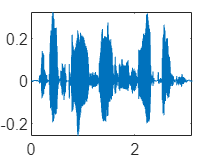

[y1, fs]=audioread('welcome.wav');
sound(y1, fs);	% 播放此音訊
time=(1:length(y1))/fs;
plot(time, y1)

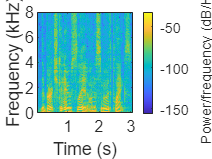

spectrogram(y1, 1024, 1000, [], fs, 'yaxis')

- 請設計兩個filter(high pass與low pass)並對Q3錄製的訊號濾波   **(10分)**

- 畫出濾波後訊號之頻譜圖與波型圖，並與濾波前訊號比較

- 低頻少很多，高頻少很多

    (high pass與low pass)           **(15分)**

[x, fs]=audioread('welcome.wav');
sound(x, fs);	% 播放此音訊
plot(time, x)

spectrogram(x, 1024, 1000, [], fs, 'yaxis')

a=[1]

a = 1

b=[1/5,1/5,1/5,1/5,1/5]

b =     0.2000    0.2000    0.2000    0.2000    0.2000


[b,a]= butter(12,(1000/(fs/2)),"low")

b = 1.0e-06 *

    0.0008    0.0101    0.0555    0.1851    0.4165    0.6664    0.7775    0.6664    0.4165    0.1851    0.0555    0.0101    0.0008


a =     1.0000   -8.9923   37.3600  -94.7720  163.4004 -201.6339  182.5274 -122.0883   59.8667  -20.9822    4.9880   -0.7220    0.0481


y=filter(b,a,x)

y =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


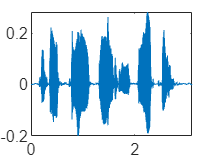

plot(time, y)

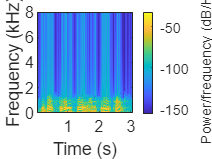

spectrogram(y, 1024, 1000, [], fs, 'yaxis')


a=[1]

a = 1

b=[1,-1]

b =      1    -1


[b,a]= butter(12,(1000/(fs/2)),"high")

b =     0.2193   -2.6320   14.4759  -48.2529  108.5690 -173.7104  202.6622 -173.7104  108.5690  -48.2529   14.4759   -2.6320    0.2193


a =     1.0000   -8.9923   37.3600  -94.7720  163.4004 -201.6339  182.5274 -122.0883   59.8667  -20.9822    4.9880   -0.7220    0.0481


y=filter(b,a,x)

y =          0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


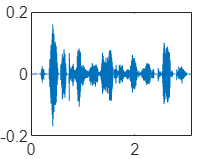

plot(time, y)

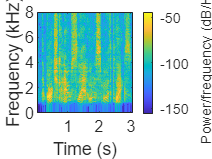

spectrogram(y, 1024, 1000, [], fs, 'yaxis')

- 請用自己手機錄音，並存成wav檔(repeat Q3)

- 試比較手機與電腦麥克風之差異